run('BASIC.m')

## generate Data

Question_mark='Q11';
[uc,t,Status,tfinal]=Datagen(2,T_s,180,0.01,poly([0.2 0.8]));

Status = '-Cololerd NOISE-'

Titlework=[Question_mark,Status]

Titlework = 'Q11-Cololerd NOISE-'

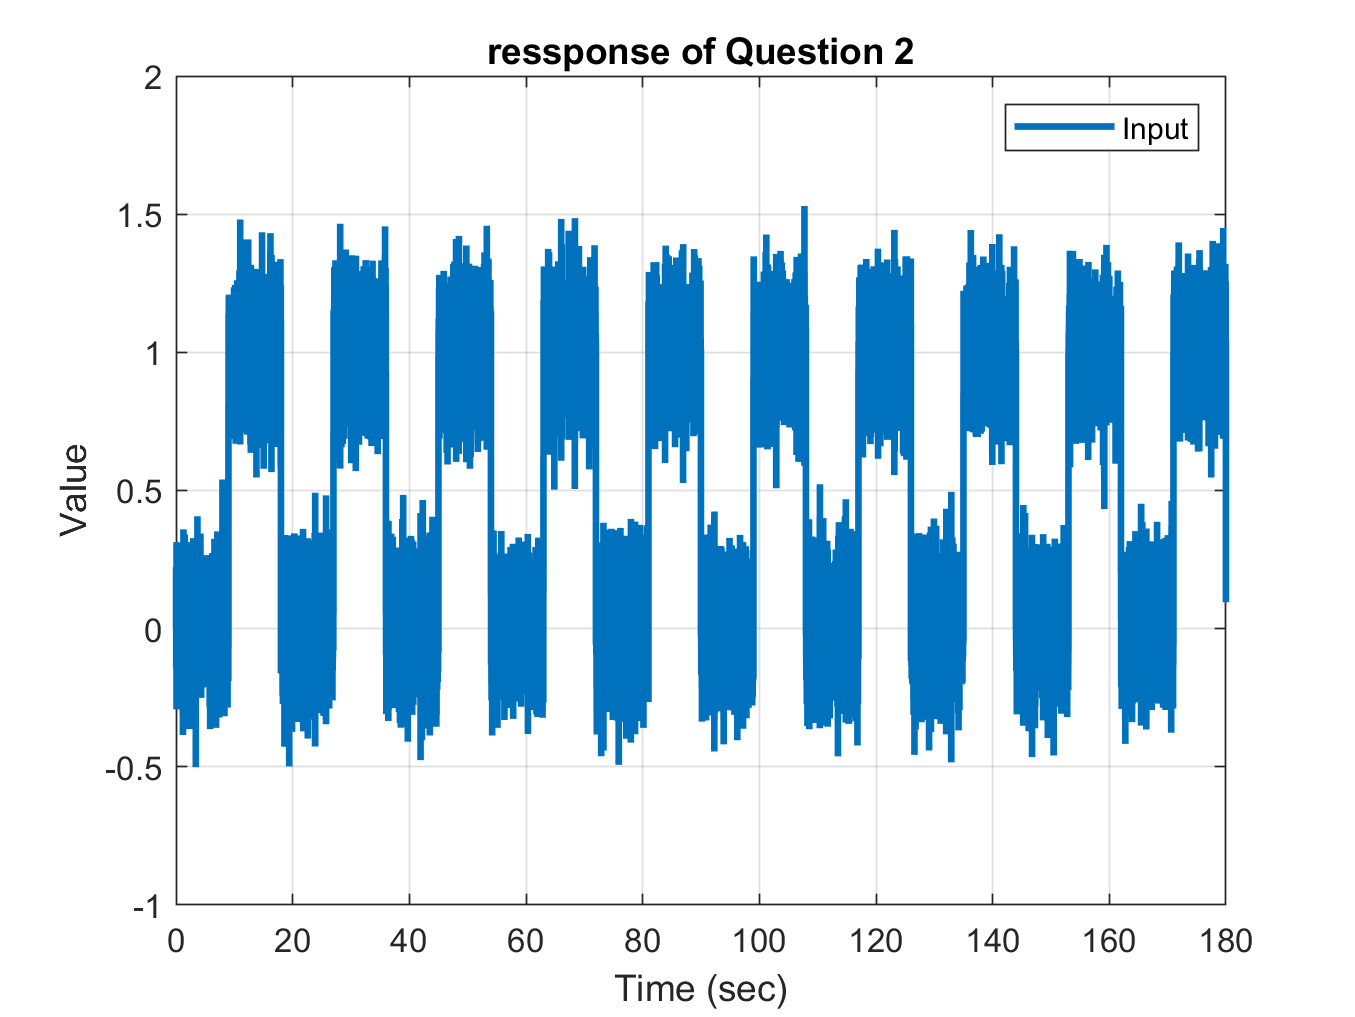

%y = lsim(sys_discret  ,uc ,t);
plot(t,uc ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;
print(gcf,[Titlework , num2str(plot_counter) ' Refrence .png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Assumption

%choose number of parameters
Parameters_in_den=2;
Parameters_in_num=2;
number_R=2

number_R = 2

A_m=poly([0.8 0.8]);


B_m=(sum(A_m)/sum(B))*B;
sys_ref=tf(B_m,A_m,T_s)

sys_ref =
 
  0.1538 z - 0.1138
  ------------------
  z^2 - 1.6 z + 0.64
 
Sample time: 0.01 seconds
Discrete-time transfer function.



y_ref_plant = lsim(sys_discret  ,uc ,t)';
%y_ref       = lsim(sys_ref , uc , t) ;

deg_A=Parameters_in_num+1;
deg_B=Parameters_in_den  ;
Nv_sys=Parameters_in_den+Parameters_in_num;
B_m=[sum(A_m),zeros(1,(deg_A-deg_B)+1)];

A_o=[1 0];

d0 = deg_A-deg_B ;
A_c_prim=conv(A_m,A_o);
deg_A_c_prim=numel(A_c_prim)-1;
%L = deg_A_c_prim-d0;L = 2

##     RLS

number_S=number_R;Nv =number_R*2 ;

N = numel(t) ;
%% initial parameters
A0 = [1 0 0];
n = numel(A)-1 ;
m = numel(B)-1 ;
d0 = n-m ;
A0Am = conv(A0 , A_m) ;
Na0am = numel(A0Am)-1 ;

theta_sys=1*ones(Nv_sys,1);
teta = 10*ones(Nv,1);

u  = uc                 ;  % initial effort control
uf = uc                 ;  % initial filtered effort control
yf = 0.1*ones(100 , 1)  ;  % initial filtered output 
ucf= uc                 ;  % initial filtered command signal
P_cont = 1e12*eye(Nv);
P_sys  = 1e12*eye(Nv_sys);
% R=zeros(Nv,N);
% S=zeros(Nv,N);
y=zeros(1,N)';
var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);

###         RLS System

for i = Nv+1:N
    y(i) =  -A(2:end)*y(i-1:-1:i-n)+B*(u(i-1:-1:i-n)) ;
    if i<20
        phi_sys = [(y(i-1:-1:i-Parameters_in_num))' , (u(i-1:-1:i-Parameters_in_den))']';
        [theta_sys,P_sys]=RLS(theta_sys,phi_sys,P_sys,Nv_sys,y(i));
        Aest=[1 -theta_sys(1:Nv_sys/2 ,end)'];
        Best=theta_sys(Nv_sys/2 +1:Nv_sys,end)';

        A_est(1:Parameters_in_den+1,i)=Aest';
        B_est(1:Parameters_in_den  ,i)=Best';
    else
        phi_sys = [(y(i-1:-1:i-Parameters_in_num))' , (u(i-1:-1:i-Parameters_in_den))']';
        [theta_sys,P_sys]=RLS(theta_sys,phi_sys,P_sys,Nv_sys,y(i));
        Aest=[1 -theta_sys(1:Nv_sys/2 ,end)'];
        Best=theta_sys(Nv_sys/2 +1:Nv_sys,end)';



        B_plus=1;
        betaa=sum(A_m)/sum(Best);
        A_c=conv(A_c_prim,B_plus);
        [R_prim,Si] = Diophantine(A,B ,A_c_prim);
        S(i,:)=Si;
        T(i,:)=conv(betaa,A_o);
        R(i,:)=conv(R_prim,B_plus);

        var1=conv(Best,T(i,:));      narv1=numel(var1)      ;
        var2=A_c(2:end)     ;     narv2=numel(A_c(2:end));
        var3=conv(Aest,T(i,:)) ;     narv3=numel(var3)      ;

        y(i)     =var1*uc(i:-1:i-narv1+1)-var2*y(i-1:-1:i-narv2);
        u(i)=var3*uc(i:-1:i-narv3+1)-var2*u(i-1:-1:i-narv2);

        A_est(1:Parameters_in_den+1,i)=Aest';
        B_est(1:Parameters_in_den  ,i)=Best';
    end
    mean_y(i)=mean(y(1:i));   var_y(i)=var(y(1:i)); ACLS_y(i)=y(i)^2+ACLS_y(i-1);
    mean_u(i)=mean(u(1:i));   var_u(i)=var(u(1:i)); ACLS_u(i)=u(i)^2+ACLS_u(i-1);
end

General Input v.s. Output

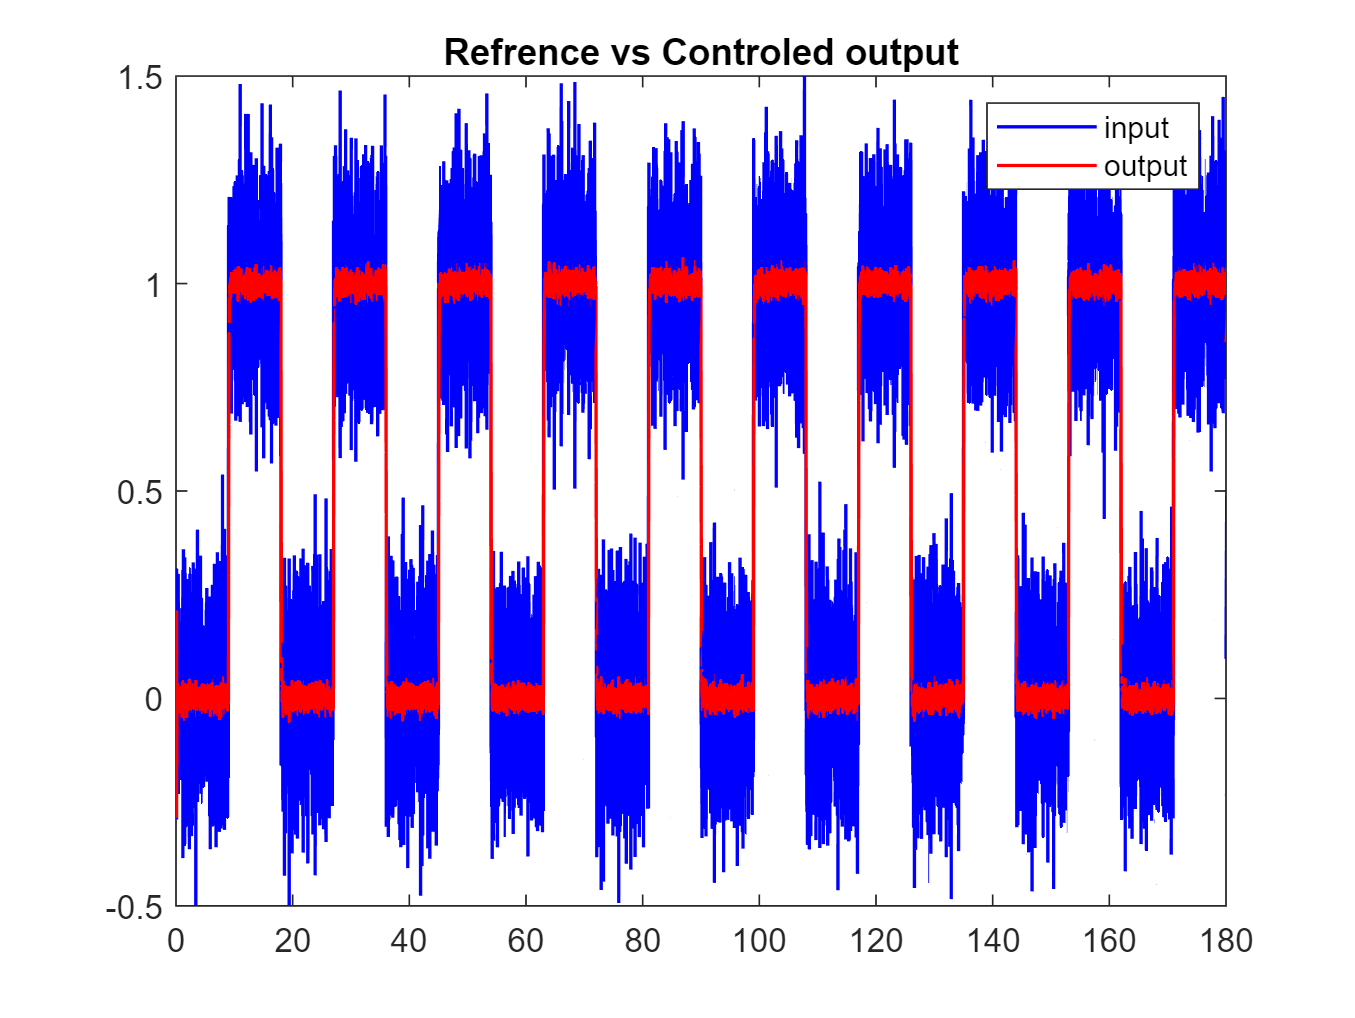

plot(t,uc,'b',t,y,'r','LineWidth',1)
title('Refrence vs Controled output')
legend('input','output')
xlim('auto')
ylim([-0.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Refrence vs Controled output.png'],'-dpng','-r400');

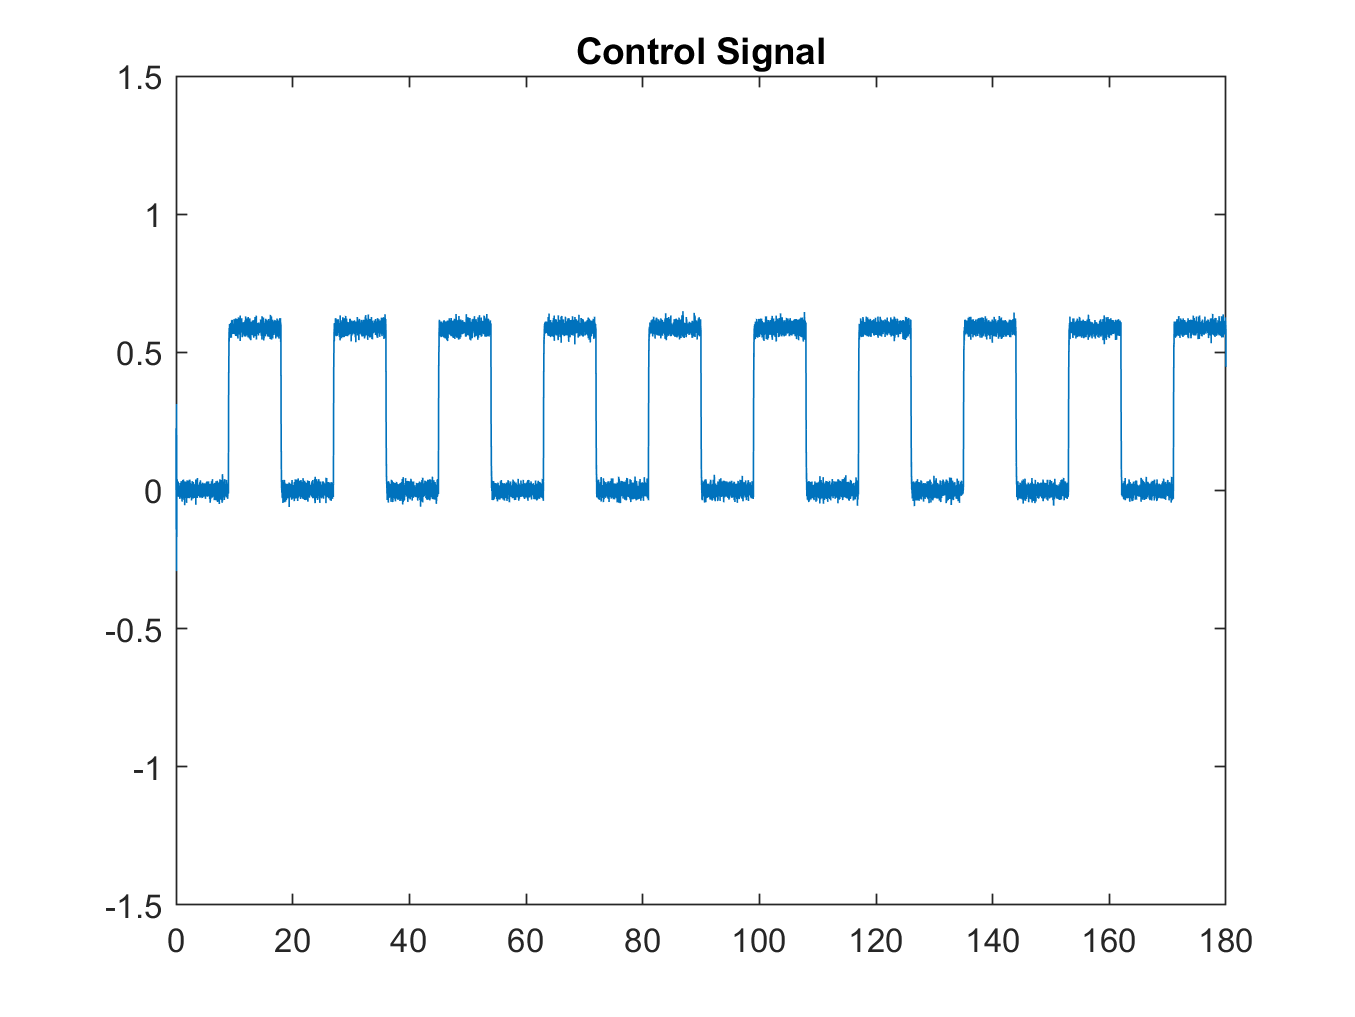

plot_counter=plot_counter+1;

plot(t,u)
title('Control Signal')
xlim('auto')
ylim([-1.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

RLS Convergence of R UND S

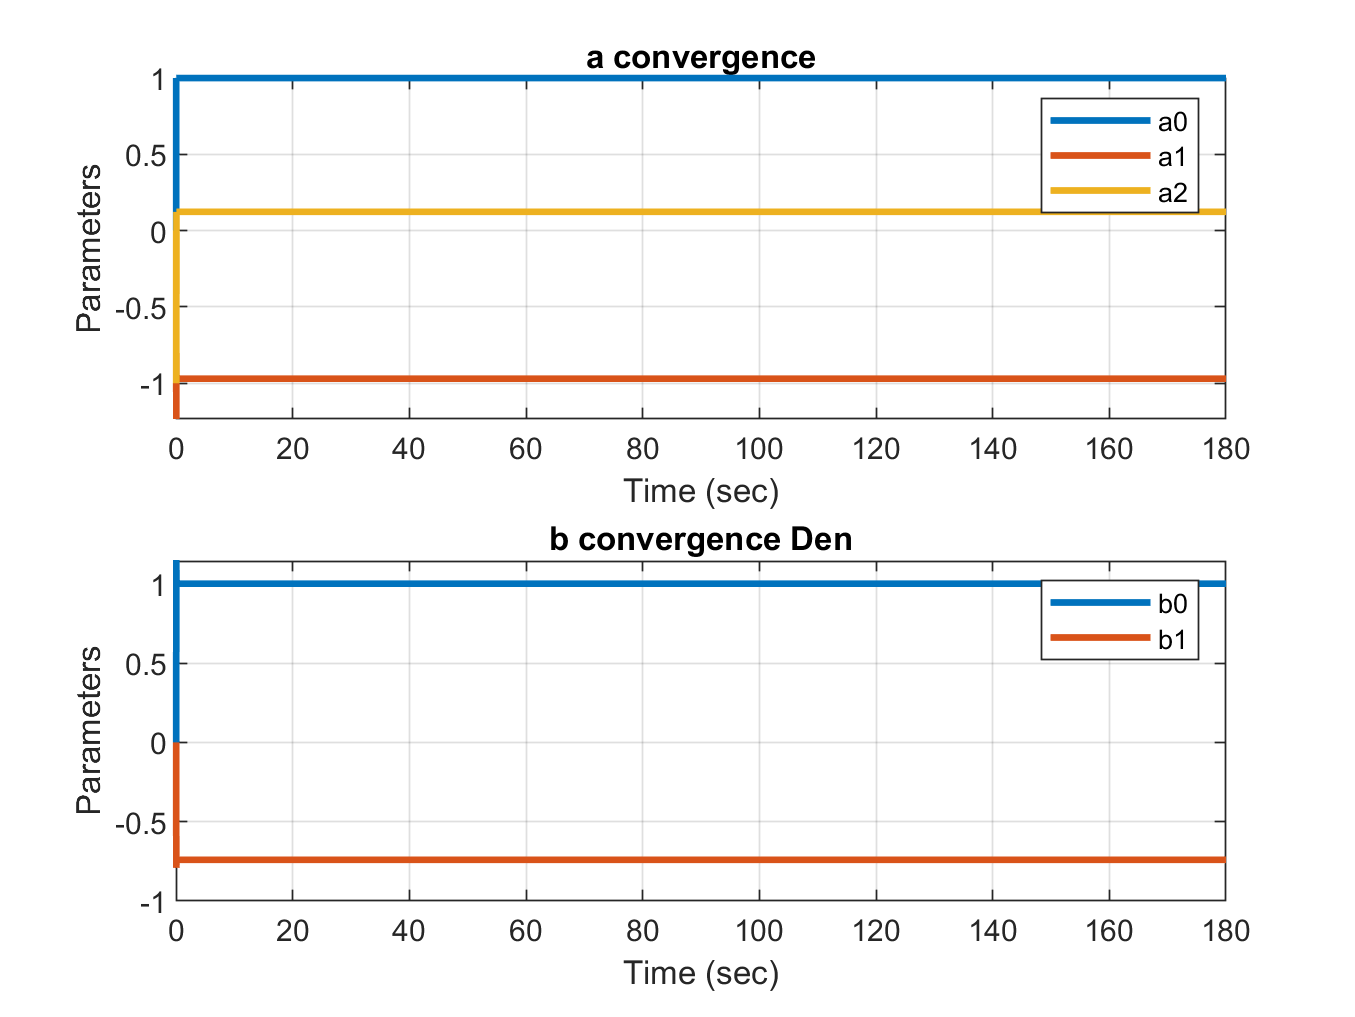

RLS_Convergence(Nv_sys/2 +1,A_est,'a',Nv_sys/2,B_est,'b',t,Titlework,1,plot_counter)

        plot_counter=plot_counter+1;

## Variance plotting

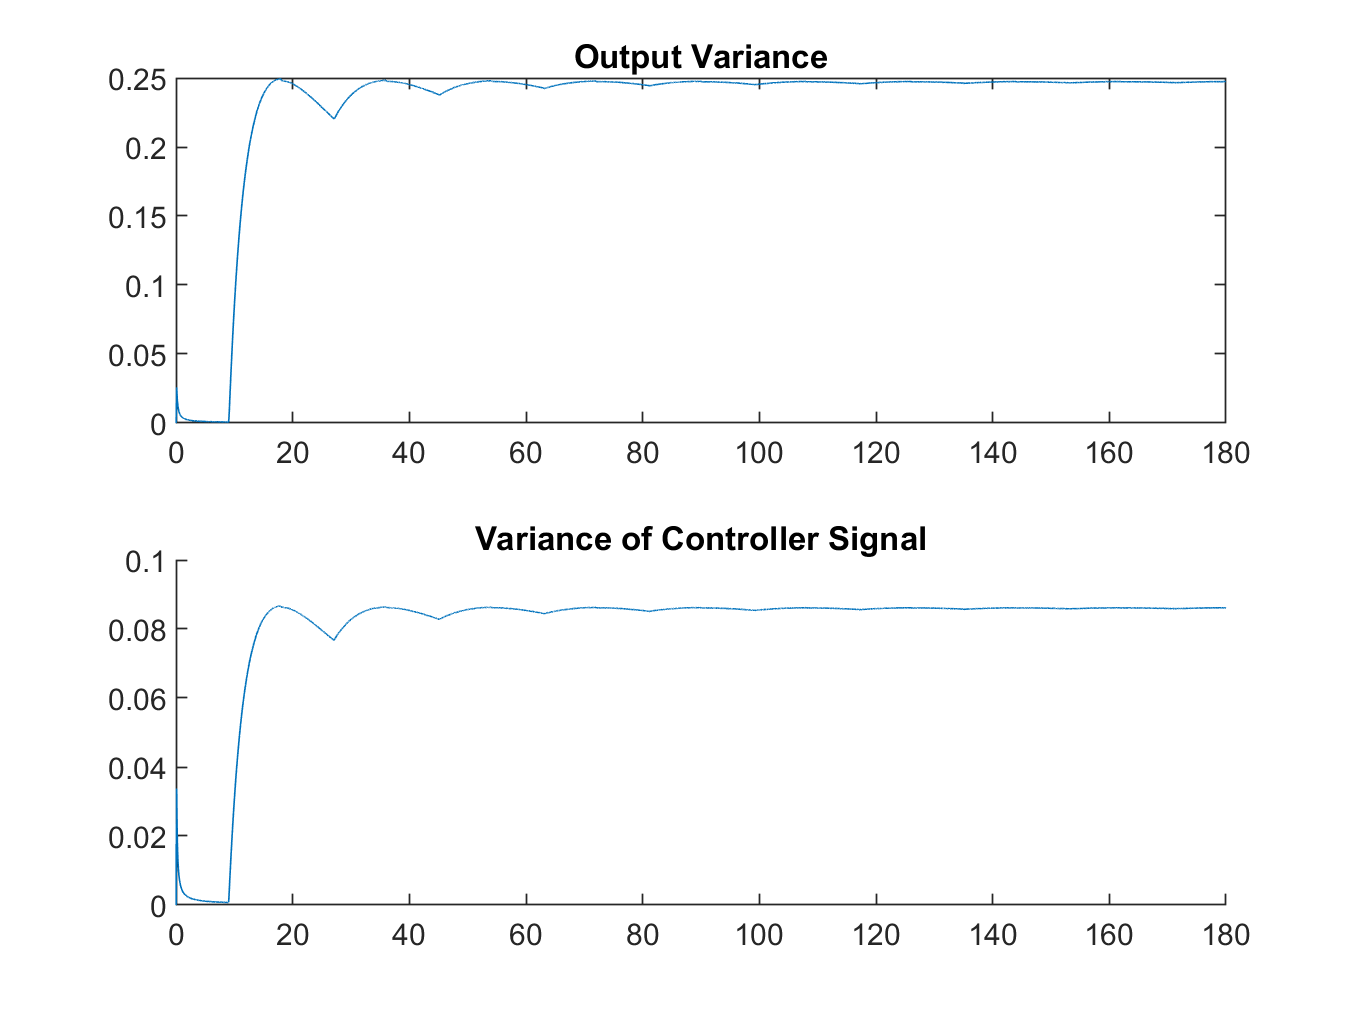

figure
subplot(211)
plot(t,var_y)
hold on
title('Output Variance')

subplot(212)
hold on
title('Variance of Controller Signal')
plot(t,var_u)
print(gcf,[Titlework , num2str(plot_counter) ' Variance.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Mean plotting

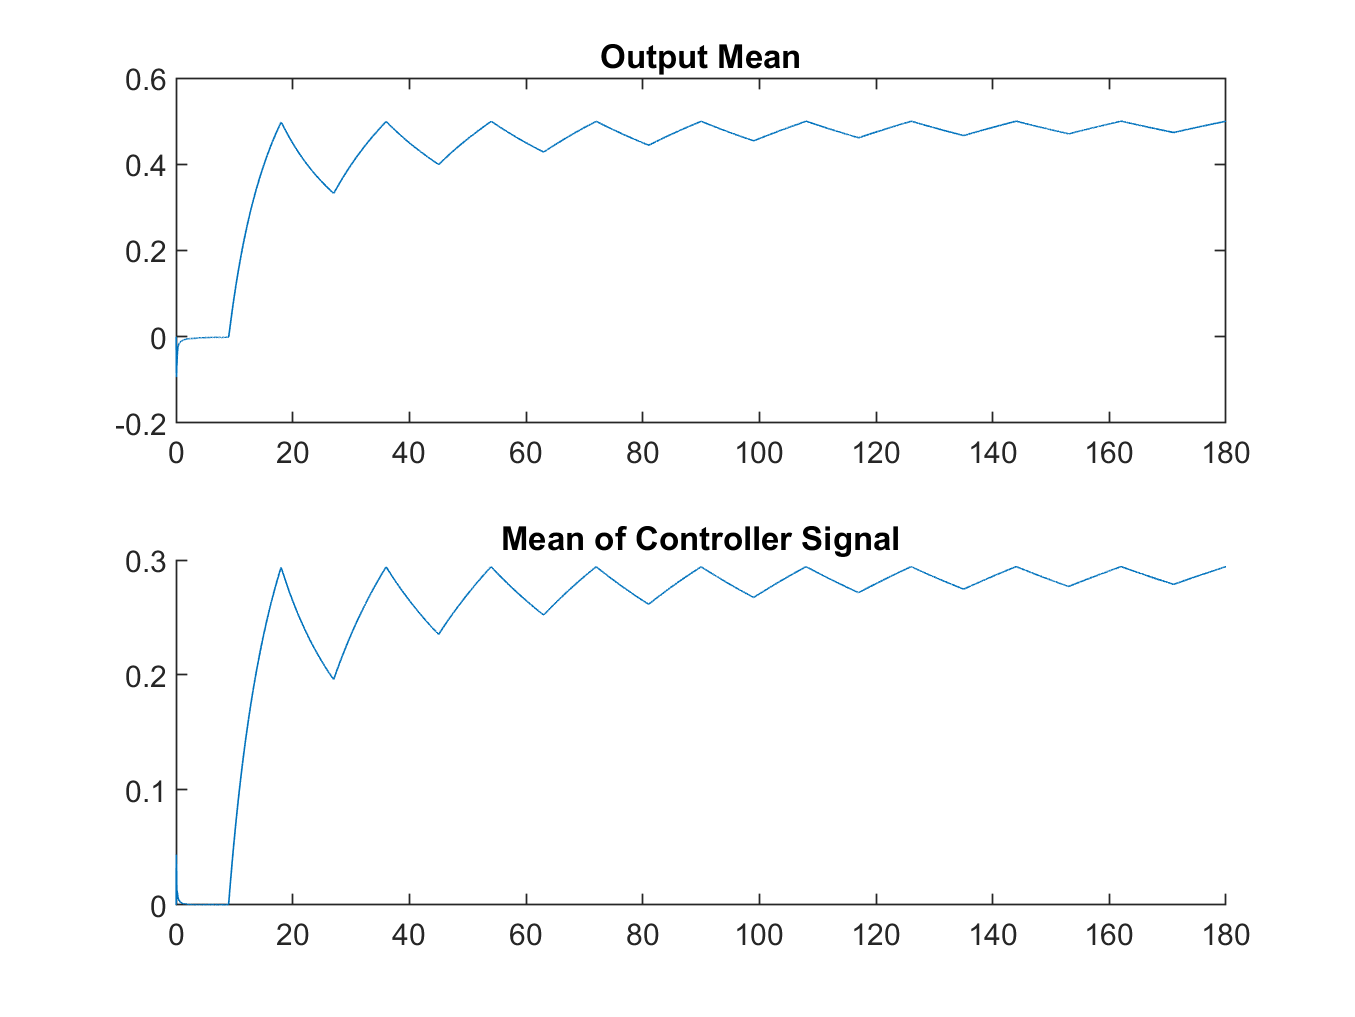

figure
subplot(211)
plot(t,mean_y)
hold on
title('Output Mean')

subplot(212)
hold on
plot(t,mean_u)
title('Mean of Controller Signal')
print(gcf,[Titlework , num2str(plot_counter) ' mean.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Accumulated loss plotting

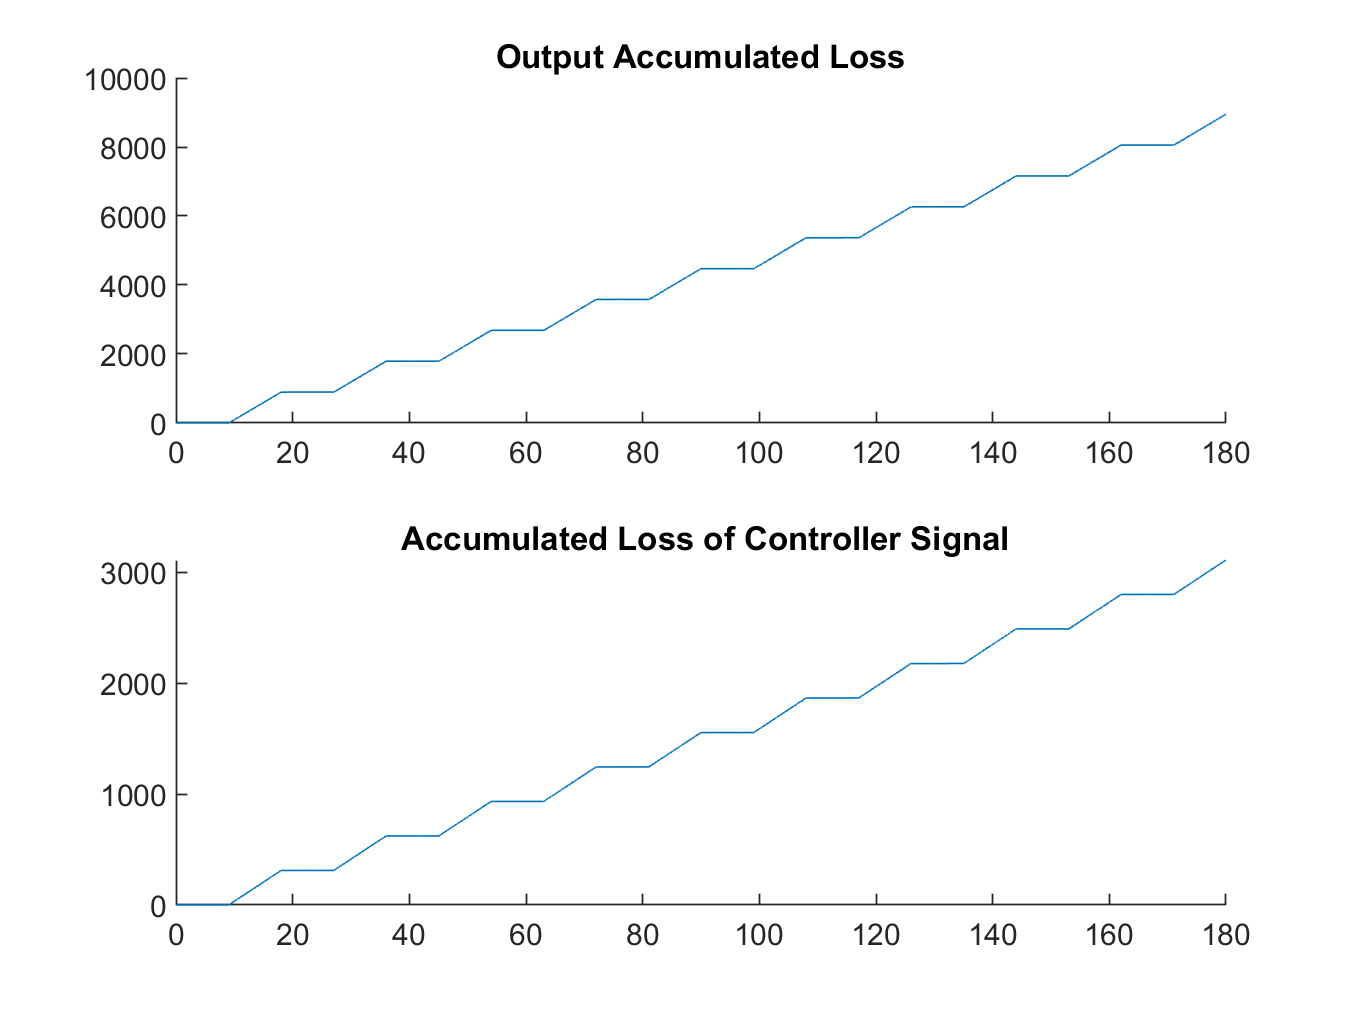

figure
subplot(211)
hold on
plot(t,ACLS_y)
title('Output Accumulated Loss')

subplot(212)
hold on
title(' Accumulated Loss of Controller Signal')
plot(t,ACLS_u)
print(gcf,[Titlework , num2str(plot_counter) ' Accumulated Loss.png'],'-dpng','-r400');

plot_counter=plot_counter+1;